# Appello del 19/06/2018

## 1 Esercizio 1.

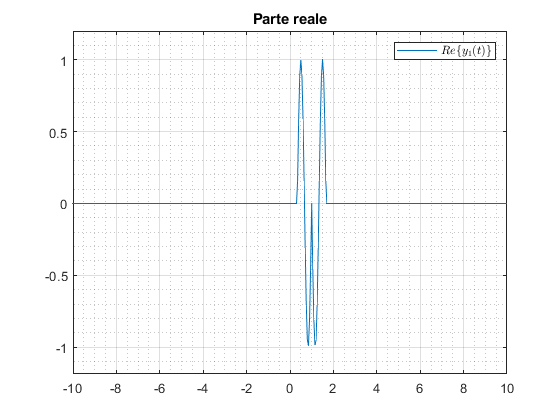

clear, close all;
t = -100:0.05:100;
x = 4 * tri(t * 1.5) + exp(t - 5) .* rect(t - 5);
tau = t - 1;
y1 = sin(pi / 2 * 4 * tri(tau * 1.5) + exp(tau - 5) .* rect(tau - 5));
y2 = convoluzione(t, x, exp(t) .* gradino(-t - 2));

rappresentaUnSegnale(t, y1, 'y_{1}(t)');
axis([-10 10 min(y1) - abs(0.1 * min(y1)) - 0.1 max(y1) + abs(0.1 * max(y1)) + 0.1]);

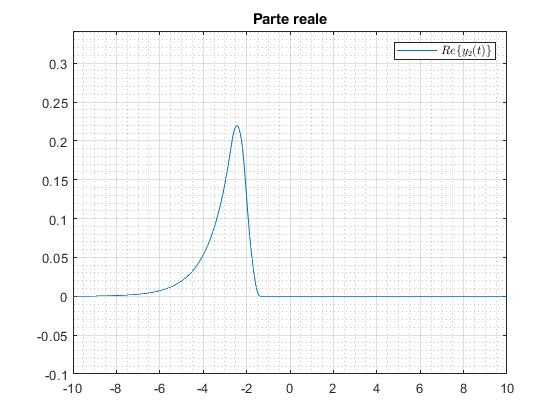


rappresentaUnSegnale(y2(1, :), y2(2, :), 'y_{2}(t)');
axis([-10 10 min(y2(2, :)) - abs(0.1 * min(y2(2, :))) - 0.1 max(y2(2, :)) + abs(0.1 * max(y2(2, :))) + 0.1]);

## 1 Esercizio 2.

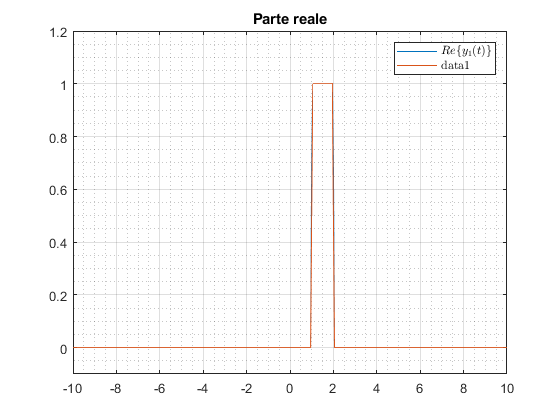

clear, close all;
t = -100:0.05:100;
x = rect(t - 1 / 2);
tau = t - 1;
y1 = sin(pi / 2 * rect(tau - 1 / 2));
y2 = convoluzione(t, x, exp(t) .* gradino(-t - 2));

y1_analitico = rect(t - 3 / 2);
y2_analitico = (exp(-2) - exp(t - 2)) .* rect(t + 1 / 2) + (exp(t - 1) - exp(t - 2)) .* gradino(-t - 1);

err_y1_y1_analitico = abs(y1 - y1_analitico);
err_y2_y2_analitico = abs(y2(2, :) - y2_analitico);

rappresentaUnSegnale(t, y1, 'y_{1}(t)'), hold on, plot(t, y1_analitico);
axis([-10 10 min(y1) - abs(0.1 * min(y1)) - 0.1 max(y1) + abs(0.1 * max(y1)) + 0.1]);

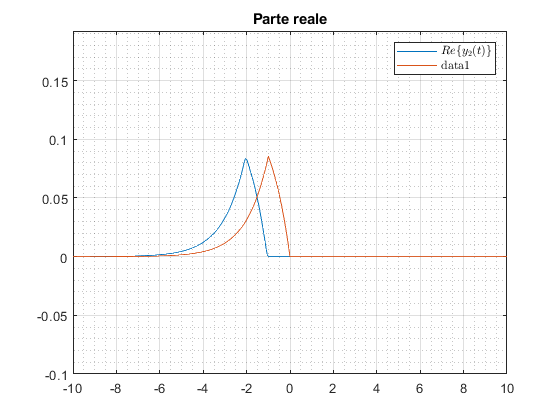


rappresentaUnSegnale(t, y2(2, :), 'y_{2}(t)'), hold on, plot(t, y2_analitico);
axis([-10 10 min(y2(2, :)) - abs(0.1 * min(y2(2, :))) - 0.1 max(y2(2, :)) + abs(0.1 * max(y2(2, :))) + 0.1]);


p_err_y1_y1_analitico = potenza(t, err_y1_y1_analitico);
p_err_y2_y2_analitico = potenza(t, err_y2_y2_analitico);

## 2 Esercizio 1.

clear, close all;
t = -10:0.05:10;
x1 = q(t, 1, 3, 1);
x2 = q(t, 1, 3, 2);
x3 = q(t, 1, 3, 3);

p1 = potenza(t, x1);
p2 = potenza(t, x2);
p3 = potenza(t, x3);

## 2 Esercizio 2.

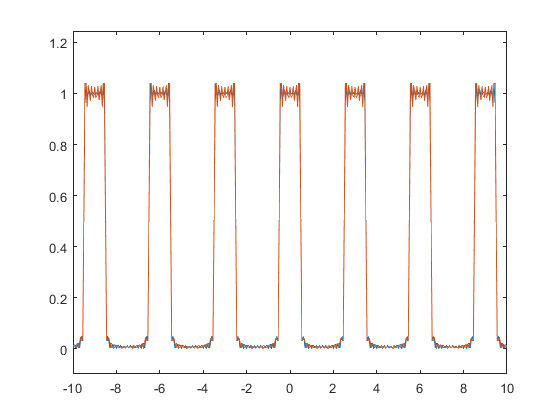

clear, close all;
t = -10:0.05:10;
x1 = q(t, 1, 3, 1);
x2 = q(t, 1, 3, 2);
x3 = q(t, 1, 3, 3);
x1S = serieDiFourier(t, x1, 3, 39);
x2S = serieDiFourier(t, x2, 3, 39);
x3S = serieDiFourier(t, x3, 3, 39);

x1S_analitico = zeros(size(x1));
x2S_analitico = zeros(size(x1));
x3S_analitico = zeros(size(x1));
for k = -20:20
	x1S_analitico = x1S_analitico + 1 / 3 * sinc(k / 3) * exp(1i * 2 * pi * k / 3 * t);
	x2S_analitico = x2S_analitico + 1 / 3 * 2 * sinc(2 * k / 3) * exp(1i * 2 * pi * k / 3 * t);
	x3S_analitico = x3S_analitico + 1 / 3 * 3 * sinc(k) * exp(1i * 2 * pi * k / 3 * t);
end

err_x1S_x1S_analitico = abs(x1S - x1S_analitico);
err_x2S_x2S_analitico = abs(x2S - x2S_analitico);
err_x3S_x3S_analitico = abs(x3S - x3S_analitico);

figure;
plot(t, abs(x1S)), hold on, plot(t, abs(x1S_analitico));
axis([-10 10 min(abs(x1S)) - abs(0.1 * min(abs(x1S))) - 0.1 max(abs(x1S)) + abs(0.1 * max(abs(x1S))) + 0.1]);

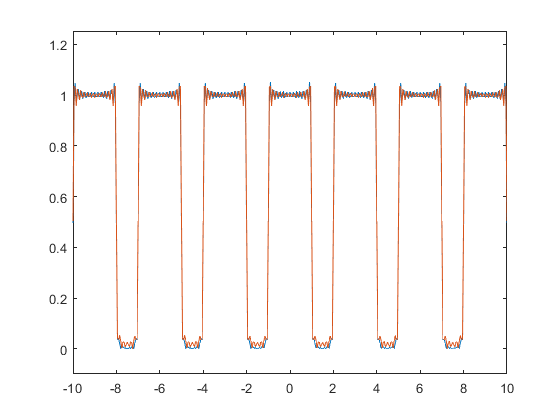


figure;
plot(t, abs(x2S)), hold on, plot(t, abs(x2S_analitico));
axis([-10 10 min(abs(x2S)) - abs(0.1 * min(abs(x2S))) - 0.1 max(abs(x2S)) + abs(0.1 * max(abs(x2S))) + 0.1]);

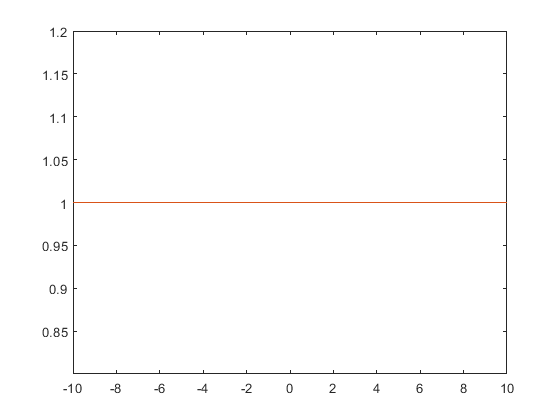


figure;
plot(t, abs(x3S)), hold on, plot(t, abs(x3S_analitico));
axis([-10 10 min(abs(x3S)) - abs(0.1 * min(abs(x3S))) - 0.1 max(abs(x3S)) + abs(0.1 * max(abs(x3S))) + 0.1]);


p_err_x1S_x1S_analitico = potenza(t, err_x1S_x1S_analitico);
p_err_x2S_x2S_analitico = potenza(t, err_x2S_x2S_analitico);
p_err_x3S_x3S_analitico = potenza(t, err_x3S_x3S_analitico);

## 2 Esercizio 4.

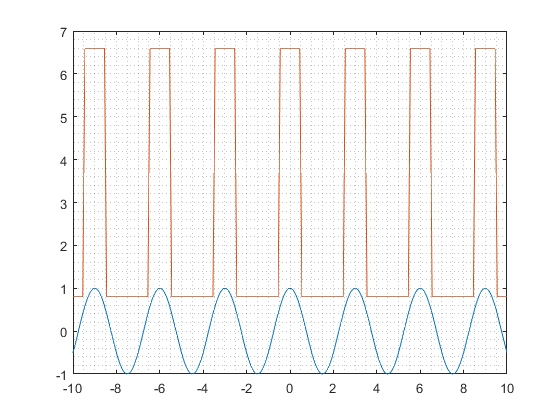

clear, close all;
t = -10:0.05:10;
x1 = q(t, 1, 3, 1);
x3 = q(t, 1, 3, 3);
y = cos(2 * pi * t / 3);

hat_y = formaBilineare(t, y, x1) * x1 + formaBilineare(t, y, x3) * x3;
err_y_hat_y = abs(y - hat_y);
figure, plot(t, y, t, hat_y), grid minor;

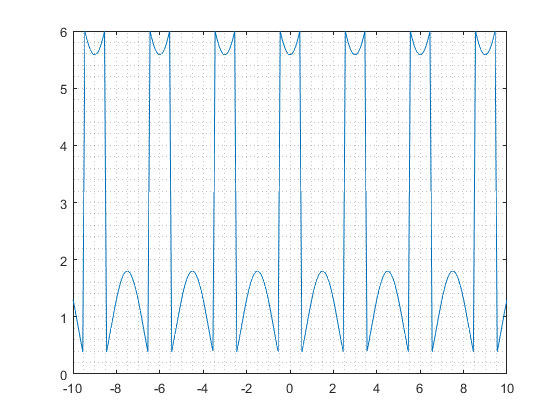

figure, plot(t, err_y_hat_y), grid minor;

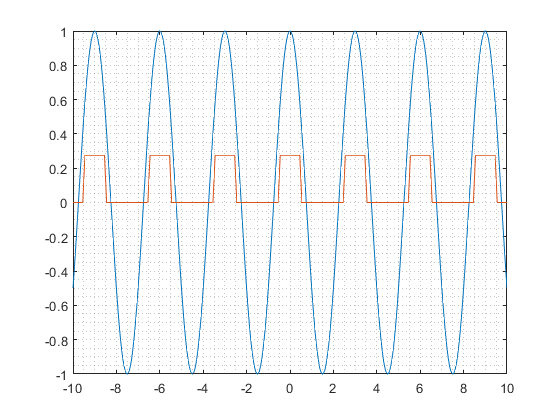

p_err_y_hat_y = potenza(t, err_y_hat_y);

hat_y_analitico = sqrt(3) / 2 / pi * x1;
err_y_hat_y_analitico = abs(y - hat_y_analitico);
figure, plot(t, y, t, hat_y_analitico), grid minor;

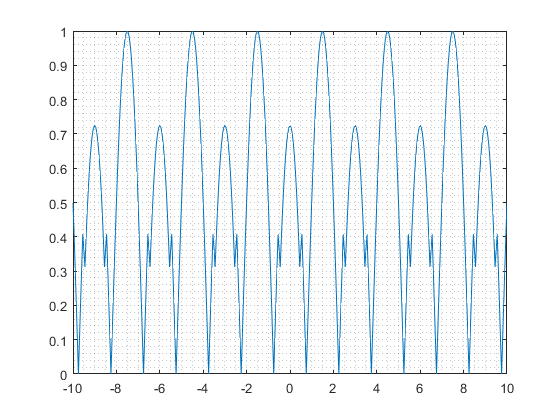

figure, plot(t, err_y_hat_y_analitico), grid minor;

p_err_y_hat_y_analitico = potenza(t, err_y_hat_y_analitico);